# PriusMatlabLib Quick Start Guide

### Installation

The third-party library including ADXL357 and MPU6050 were installed in the path of Matlab additional software. However, those libs should be installed in the Arduino package lib folder.

- Windows® and Linux® - "`arduinoio.IDERoot`/portable/sketchbook/libraries/"

- Mac- "~/Documents/Arduino/libraries/"

if ismac
    libPath = "~/Documents/Arduino/libraries/";
elseif isunix || ispc
    libPath = fullfile(arduino.supportpkg.getIDERoot, 'portable', 'sketchbook', 'libraries');
else
    error('Platform not supported')
end

thirdPartyLib = {'ADXL357', 'mpu6050'};

for f = thirdPartyLib
    f = f{1};
    copyfile(PRIUSMatlabLib.getInstallationLocation(f),fullfile(libPath, f))
end

### Example of ADXL357

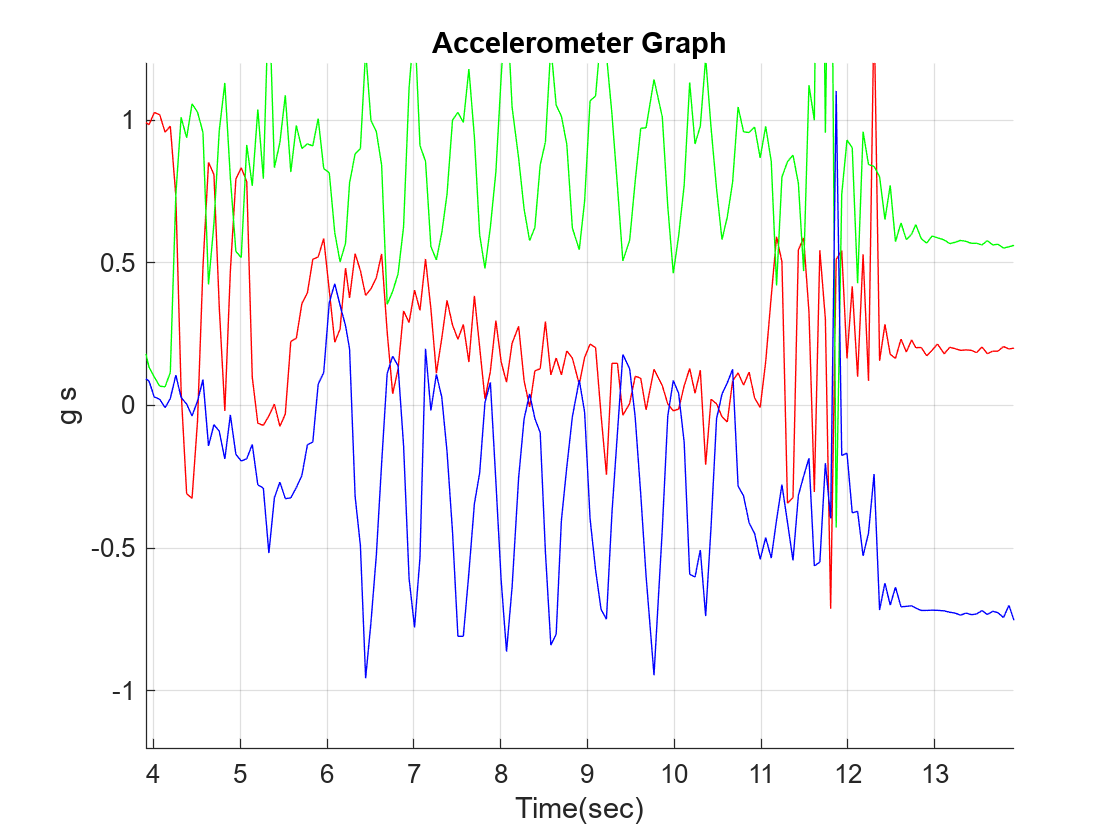

clear a sensor
a = arduino('COM3','Uno', 'libraries', 'Sensors/ADXL357Addon');
sensor = addon(a, 'Sensors/ADXL357Addon', false, 40);

figure
hold on
xLine = animatedline(NaN, NaN, 'Color', 'r');
yLine = animatedline(NaN, NaN, 'Color', 'g');
zLine = animatedline(NaN, NaN, 'Color', 'b');

ax = gca;

xlabel('Time(sec)');
ylabel('g s');
title('Accelerometer Graph');
ax.YLim = [-1.2 1.2];
grid on;

GrphaTimer = tic;

Tfs = [];

while 1
    loopTimer = tic;
    [x, y, z] = sensor.read();
    t =  toc(GrphaTimer);

    addpoints(xLine,t,x);
    addpoints(yLine,t,y);
    addpoints(zLine,t,z);

    ax.XLim = [t-10 t];
    drawnow;
    Tfs = [Tfs toc(loopTimer)];
end